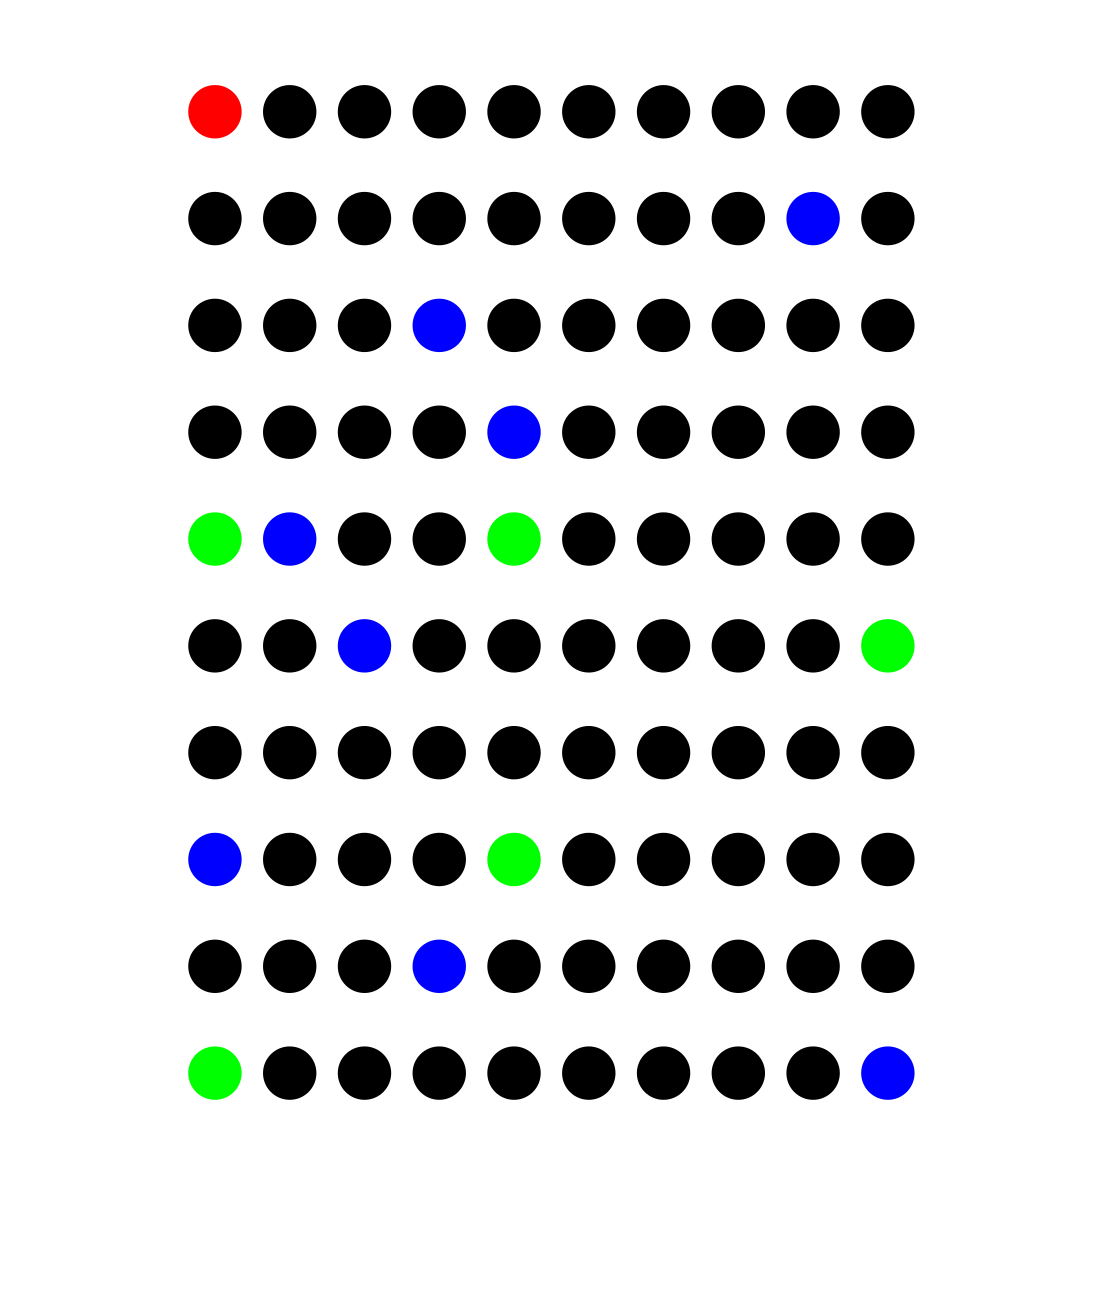

clear
clc

thisImg = imread("dotPattern.png");
imshow(thisImg)


%Count Red (Calibration) Dot
img = thisImg;
m = img(:,:,1)>128 & img(:,:,2)<128 & img(:,:,3)<128;
pixelsPerCircle=sum(sum(m)); %Use single red circle
numOfRedCircles = floor(pixelsPerCircle/pixelsPerCircle)

numOfRedCircles = 1

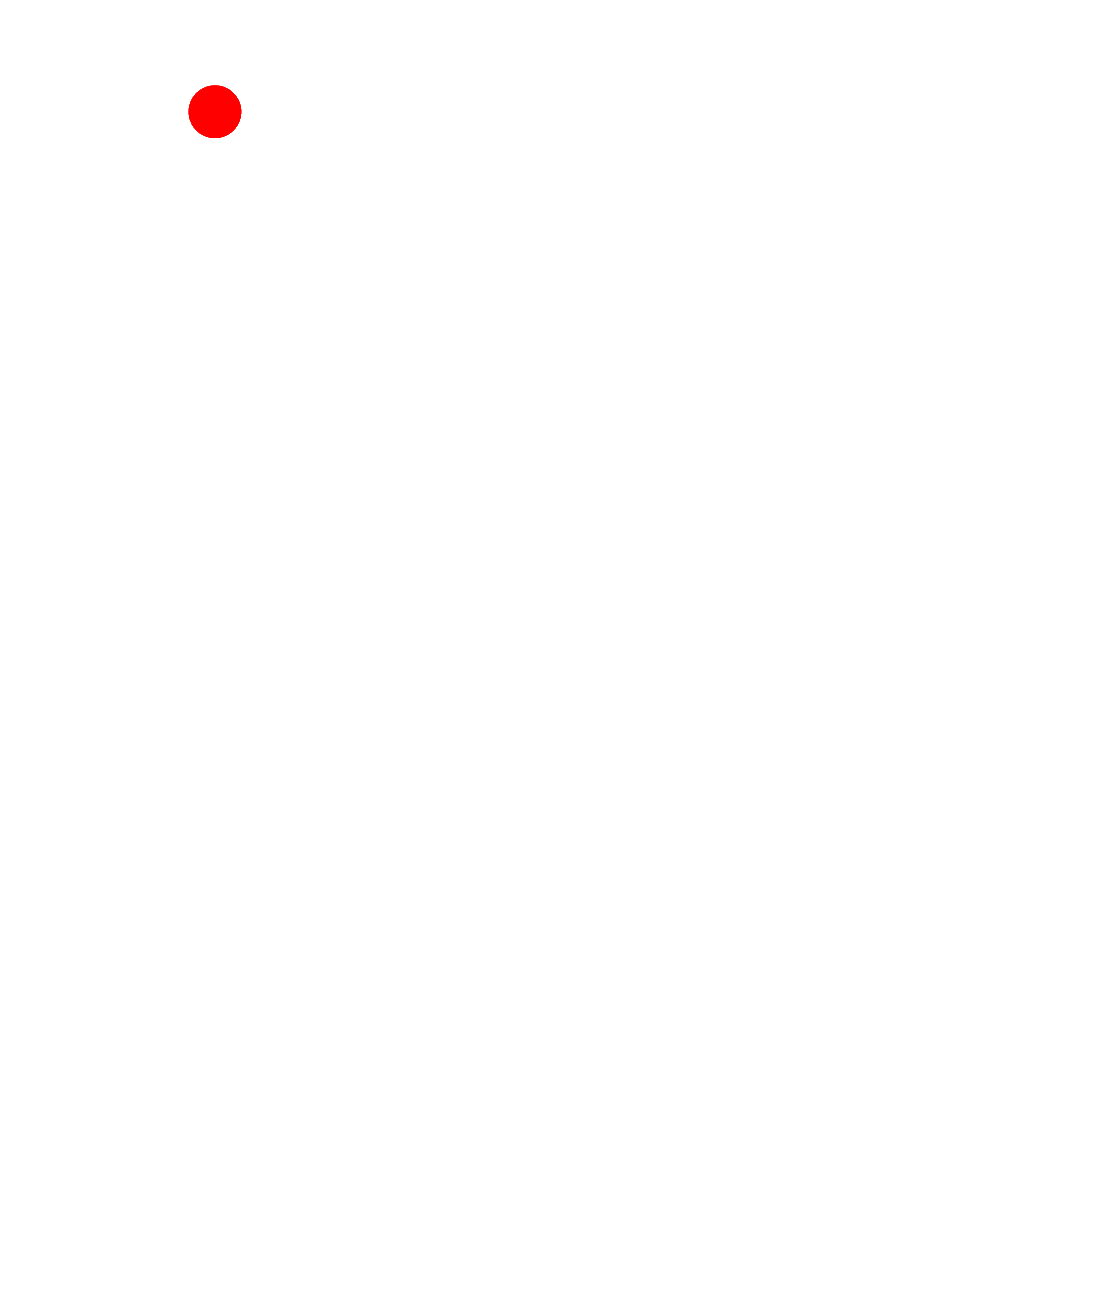

%Turn the 2D mask into a 3D mask by copying it to each RGB Layer
m3(:,:,1) = m;
m3(:,:,2) = m;
m3(:,:,3) = m;
%Apply mask to set chosen pixels to appropriate values
img(~m3) = 255;
%Show image
imshow(img)



%Count Blue Circles
img = thisImg;
m = img(:,:,1)<128 & img(:,:,2)<128 & img(:,:,3)>128;
bluePixels=sum(sum(m));
numOfBlueCircles = floor(bluePixels/pixelsPerCircle)

numOfBlueCircles = 8

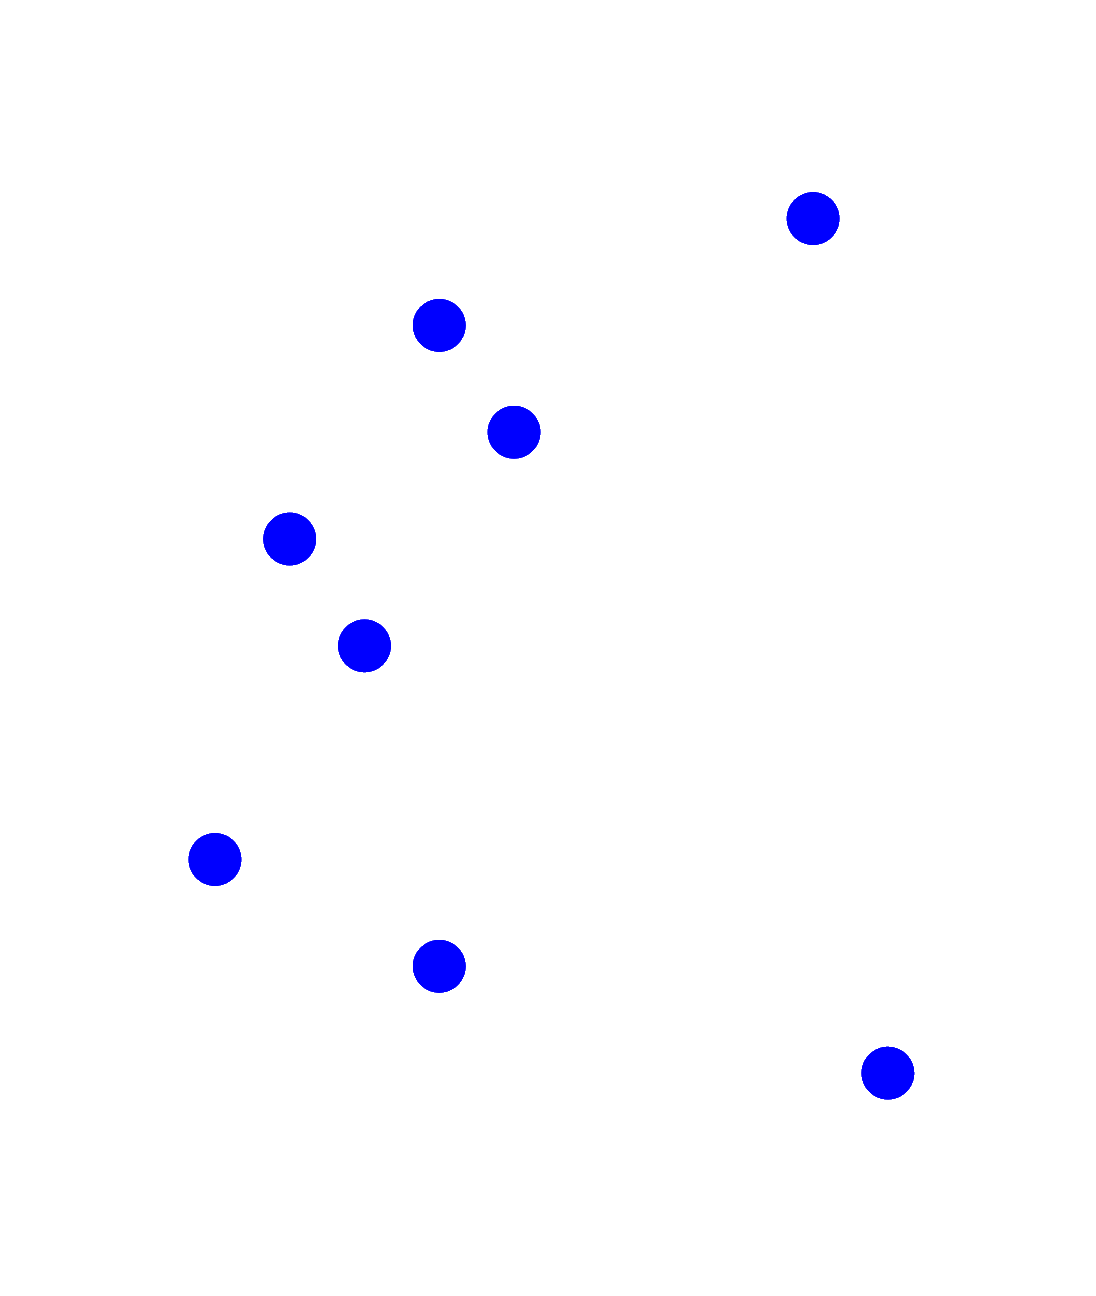

%Turn the 2D mask into a 3D mask by copying it to each RGB Layer
m3(:,:,1) = m;
m3(:,:,2) = m;
m3(:,:,3) = m;
%Apply mask to set chosen pixels to appropriate values
img(~m3) = 255;
%Show image
imshow(img)

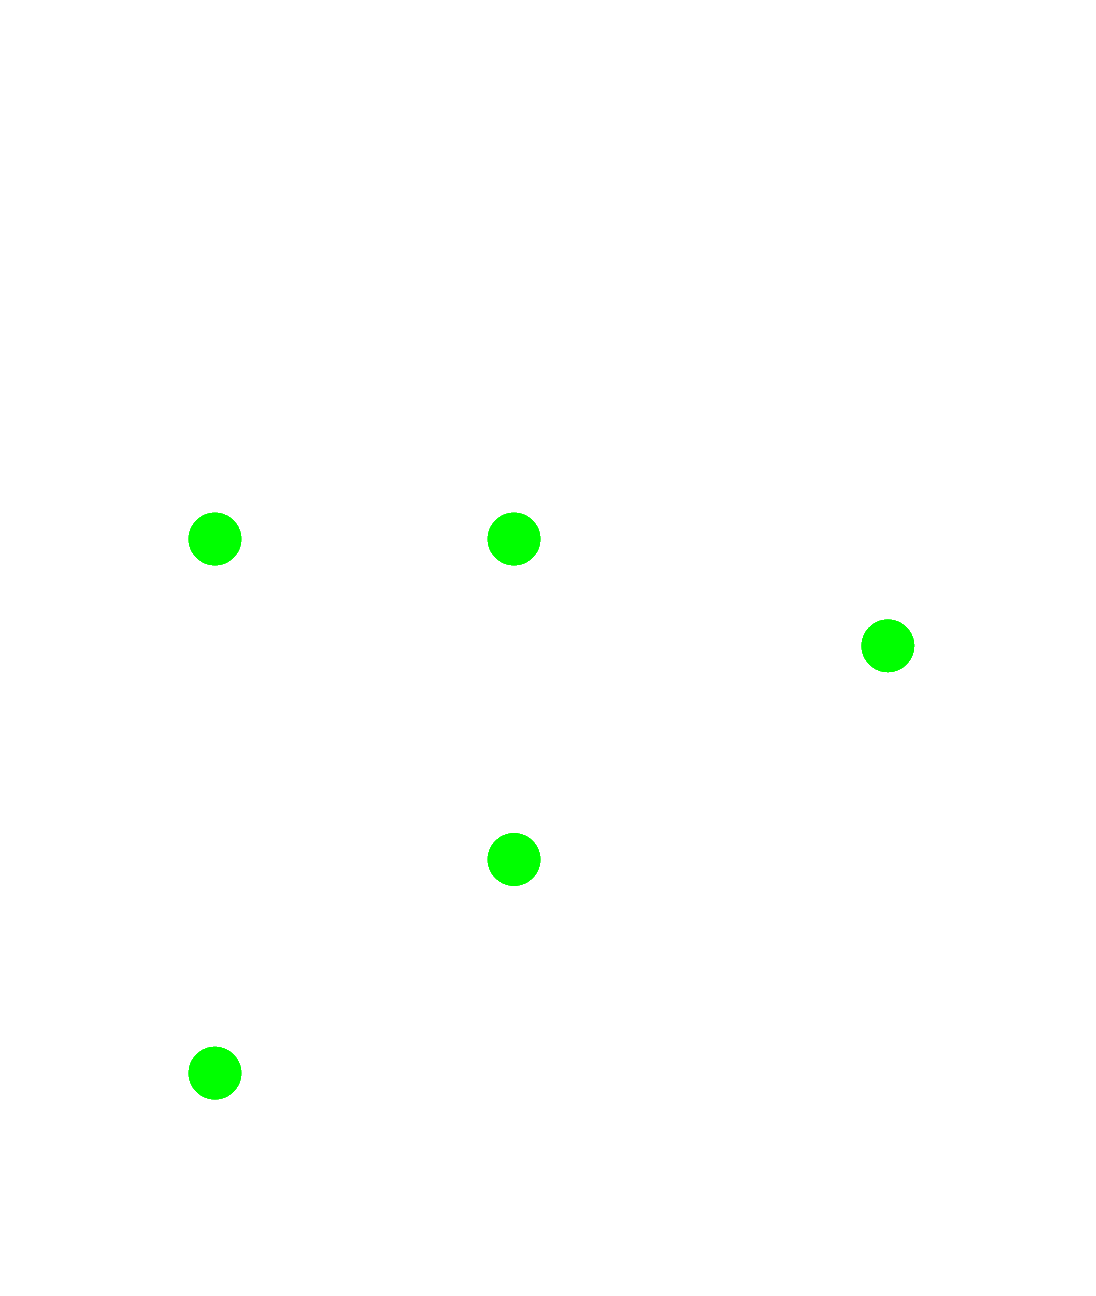



%Count Green Circles
img = thisImg;
m = img(:,:,1)<128 & img(:,:,2)>128 & img(:,:,3)<128;
greenPixels=sum(sum(m));
numOfGreenCircles = floor(greenPixels/pixelsPerCircle);
%Turn the 2D mask into a 3D mask by copying it to each RGB Layer
m3(:,:,1) = m;
m3(:,:,2) = m;
m3(:,:,3) = m;
%Apply mask to set chosen pixels to appropriate values
img(~m3) = 255;
%Show image
imshow(img)



%Count Black Circles
img = thisImg;
m = img(:,:,1)<128 & img(:,:,2)<128 & img(:,:,3)<128;
blackPixels=sum(sum(m));
numOfBlackCircles = floor(blackPixels/pixelsPerCircle)

numOfBlackCircles = 86

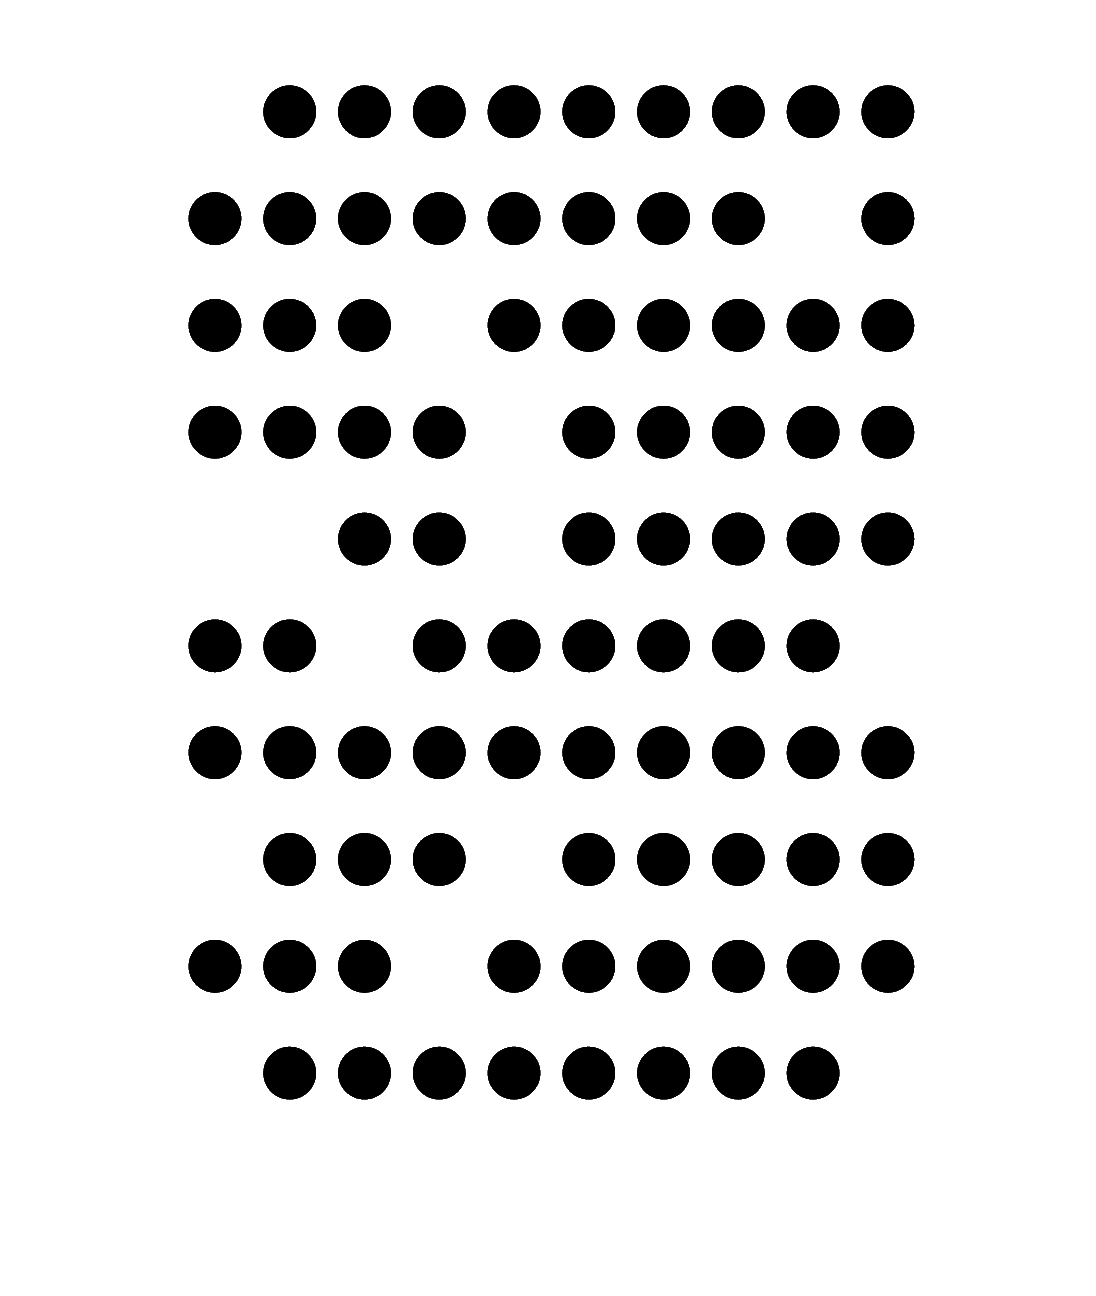

%Turn the 2D mask into a 3D mask by copying it to each RGB Layer
m3(:,:,1) = m;
m3(:,:,2) = m;
m3(:,:,3) = m;
%Apply mask to set chosen pixels to appropriate values
img(~m3) = 255;
%Show image
imshow(img)   


fprintf('Dot Summary\n')

Dot Summary


fprintf('%d \t Red Dot(s)\n',numOfRedCircles)

1 	 Red Dot(s)


fprintf('%d \t Green Dot(s)\n',numOfGreenCircles)

5 	 Green Dot(s)


fprintf('%d \t Blue Dot(s)\n',numOfBlueCircles)

8 	 Blue Dot(s)


fprintf('%d \t Black Dot(s)\n',numOfBlackCircles)

86 	 Black Dot(s)
